         0   -4.0000         0    3.9416         0
    0.1000   -3.9157    1.6465    3.8929   -0.9480
    0.2000   -3.6825    2.9404    3.7587   -1.6879
    0.3000   -3.3450    3.7169    3.5683   -2.0404
    0.4000   -2.9560    3.9922    3.3663   -1.9325
    0.5000   -2.5579    3.9293    3.1913   -1.5462
    0.6000   -2.1760    3.6889    3.0588   -1.1049
    0.7000   -1.8228    3.3667    2.9681   -0.7228
    0.8000   -1.5038    3.0103    2.9115   -0.4226
    0.9000   -1.2210    2.6466    2.8811   -0.1968
    1.0000   -0.9741    2.2929    2.8701   -0.0325
    1.1000   -0.7617    1.9610    2.8729    0.0824
    1.2000   -0.5810    1.6579    2.8852    0.1579
    1.3000   -0.4290    1.3872    2.9035    0.2024
    1.4000   -0.3024    1.1493    2.9249    0.2237
    1.5000   -0.1981    0.9428    2.9476    0.2284
    1.6000   -0.1129    0.7651    2.9702    0.2219
    1.7000   -0.0442    0.6132    2.9918    0.2086
    1.8000    0.0105    0.4840    3.0118    0.1917
    1.9000    0.0533    0.3747 

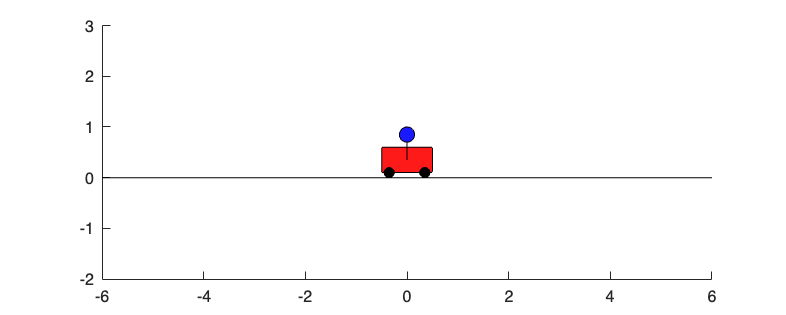


cart_pendulum_main();


function draw_cart_pendulum(y,m, M, L)
  x = y(1);
  theta = y(3);
  
  W = 1*sqrt(M/5);    
  H = 0.5*sqrt(M/5);  
  wr = 0.2;          
  mr = 0.3*sqrt(m);    
  
  y = wr/2 + H/2;
  w1x = x - 0.9*W/2;
  w1y = 0;
  w2x = x + 0.9*W/2 - wr;
  w2y = 0;
  
  px = x - L*sin(theta);
  py = y - L*cos(theta);
   
  hold on;
  clf;
  axis equal;
  rectangle('Position',[x-W/2,y-H/2,W,H],'Curvature',.1,'FaceColor',[1 0.1 0.1])
  rectangle('Position',[w1x,w1y,wr,wr],'Curvature',1,'FaceColor',[0 0 0])
  rectangle('Position',[w2x,w2y,wr,wr],'Curvature',1,'FaceColor',[0 0 0])
  
  line ([-10 10], [0 0], "linestyle", "-", "color", "k");
  line ([x px], [y py], "linestyle", "-", "color", "k");
  rectangle('Position',[px-mr/2,py-mr/2,mr,mr],'Curvature',1,'FaceColor',[.1 0.1 1])
  
  xlim([-6 6]);
  ylim([-2 3]);
  set(gcf, 'Position', [200 300 1000 400]);
  drawnow
  hold off
end

function dy = cart_pendulum_dynamics(y, m, M, L, g,  u)
  sin_theta = sin(y(3));
  cos_theta = cos(y(3));
  
  denominator    =  M + m*(sin_theta^2);
  numerator_dy_2 = (u - (m*g)*sin_theta*cos_theta - (m*L)*sin_theta*y(4)^2);
  numerator_dy_4 = (-(m+M)*g*sin_theta + u*cos_theta - (m*L*y(4)^2 * sin_theta *cos_theta) ) ;

  dy(1,1) = y(2);
  dy(2,1) = numerator_dy_2/denominator ;
  dy(3,1) = y(4);
  dy(4,1) = numerator_dy_4/(L*(denominator));
end
%% Function : sim_cart_pendulum()
%% ----------------------------------------------------
%% Input:   m - Mass of pendulum bob
%%          M - Mass of cart
%%          L - Length of cart
%%          g  - Acceleration due to gravity
%%          y0 - Initial Condition of system
%%
%% Output:  t - Timestep
%%          y - Solution array
%%          
%% Purpose: This function demonstrates the behavior of cart pendulum system without 
%%          any external input (u).
%%          This integrates the system of differential equation from t0 = 0 to 
%%          tf = 10 with initial condition y0
function [t,y] = sim_cart_pendulum(m, M, L, g, y0)
  tspan = 0:0.1:10;                  %% Initialise time step           
  u = 0;                             %% No Input
  [t,y] =  ode45(@(t,y)cart_pendulum_dynamics(y, m, M, L, g, u),tspan,y0);%% Solving the differential equation    
end

%% Function : cart_pendulum_AB_matrix()
%% ----------------------------------------------------
%% Input:   m - Mass of pendulum bob
%%          M - Mass of cart
%%          L - Length of cart
%%          g  - Acceleration due to gravity
%%
%% Output:  A - A matrix of system
%%          B - B matrix of system
%%          
%% Purpose: Declare the A and B matrices in this function.
function [A, B] = cart_pendulum_AB_matrix(m , M, L, g)
  
  A = [0 1          0          0;
       0 0    -(m*g)/M         0;
       0 0          0          1;
       0 0   ((m+M)*g)/(M*L) 0];   
 
 B = [     0  ; 
        1/(M) ;
            0 ;
        -1/(M*L) ];
end

%% Function : pole_place_cart_pendulum()
%% ----------------------------------------------------
%% Input:   m - Mass of pendulum bob
%%          M - Mass of cart
%%          L - Length of cart
%%          g  - Acceleration due to gravity
%%          y_setpoint - Reference Point
%%          y0 - Initial Condition
%%
%% Output:  t - Timestep
%%          y - Solution array
%%          
%% Purpose: This function demonstrates the behavior of inverted cart pendulum with 
%%          external input using the pole_placement controller
%%          This integrates the system of differential equation from t0 = 0 to 
%%          tf = 10 with initial condition y0 and input u = -Kx where K is
%%          calculated using Pole Placement Technique.
function [t,y] = pole_place_cart_pendulum(m, M, L, g, y_setpoint, y0)
  [A,B] = cart_pendulum_AB_matrix(m, M, L, g);
  eigs  = [ -2.9 
            -3.3
            -1.0 + 0.7i
            -1.0 - 0.7i];
  K     = place(A, B, eigs);
  tspan = 0:0.1:10;
  [t,y] = ode45(@(t,y)cart_pendulum_dynamics(y, m, M, L, g, -K*(y-y_setpoint)),tspan,y0);
end

%% Function : lqr_cart_pendulum()
%% ----------------------------------------------------
%% Input:   m - Mass of pendulum bob
%%          M - Mass of cart
%%          L - Length of cart
%%          g  - Acceleration due to gravity
%%          y_setpoint - Reference Point
%%          y0 - Initial Condition
%%
%% Output:  t - Timestep
%%          y - Solution array
%%          
%% Purpose: This function demonstrates the behavior of inverted cart pendulum with 
%%          external input using the LQR controller
%%          This integrates the system of differential equation from t0 = 0 to 
%%          tf = 10 with initial condition y0 and input u = -Kx where K is
%%          calculated using LQR Controller.
function [t,y] = lqr_cart_pendulum(m, M, L, g, y_setpoint, y0)
  [A,B] = cart_pendulum_AB_matrix(m, M, L, g); 
  Q     = [150 0  0   0 ;0 50  0   0 ;0 0  200   0 ;0 0  0  10] ;
          
  R = 1;
  K     = lqr(A, B, Q, R) ; 

  tspan = 0:0.1:10;
  [t,y] = ode45(@(t,y)cart_pendulum_dynamics(y, m, M, L, g, -K*(y-y_setpoint)),tspan,y0);;
end

%% Function : cart_pendulum_main()
%% ----------------------------------------------------
%% Purpose: Used for testing out the various controllers by calling their 
%%          respective functions and observing the behavior of the system. Constant
%%          parameters like mass of cart, mass of pendulum bob etc are declared here.
function cart_pendulum_main()
  m = 1;
  M = 5;
  L = 0.5;
  g = 9.8;
  y0 = [-4.0; 0; pi+0.8; 0];
  y_setpoint = [0; 0; pi; 0];
  
  %[t,y] = sim_cart_pendulum(m, M, L, g, y0);
 %[t,y] = pole_place_cart_pendulum(m, M, L, g, y_setpoint, y0);
  [t,y] = lqr_cart_pendulum(m, M, L, g, y_setpoint, y0);
  disp([t,y]);
  for k = 1:length(t)
    draw_cart_pendulum(y(k, :), m, M, L);  
  end
end
